**Experimento de Arago**

Establecimiento de parámetros físicos 

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de la representación
Nx = 1024;
Ny = 1024;

% Condiciones de Muestreo
dx = 0.1*um;
dy = 0.1*um;

% Longitud de onda de iluminación
lambda = 650*nm;

Limite entre Espectro angular y trnasformada fresnel

zlim = Nx*dx^2/lambda  % En metros

zlim = 1.5754e-05

% Distancia a utilizar
z = 20*um;

Determinación del radio de de la abertura

n = 4 ;  % Entero
radioZonaFresnel = sqrt(n*lambda*z)

radioZonaFresnel = 7.2111e-06

Se realiza una propagación de fuente puntual para evitar efectos de difracción de abertura cuadrada

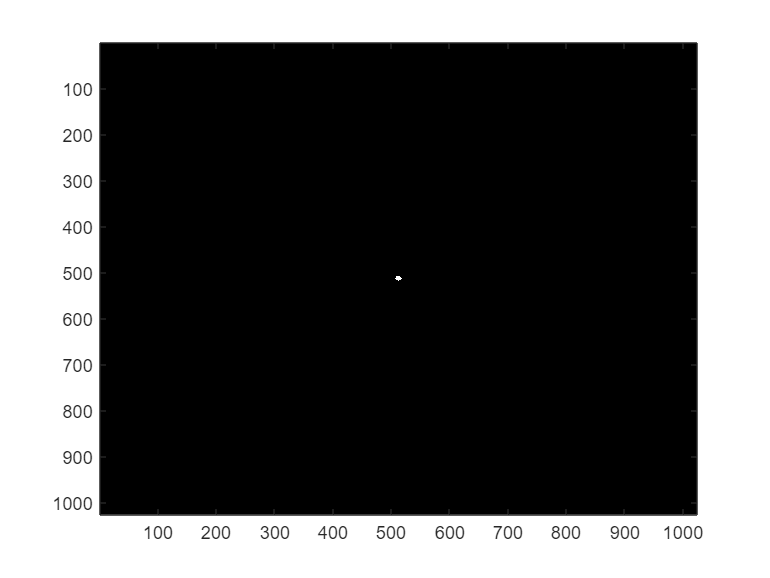

radioSpot = 0.5*um/dx;
punto = filtroCircular ([Nx/2 Ny/2],radioSpot,[Ny Nx]);
imagesc(punto)
colormap gray

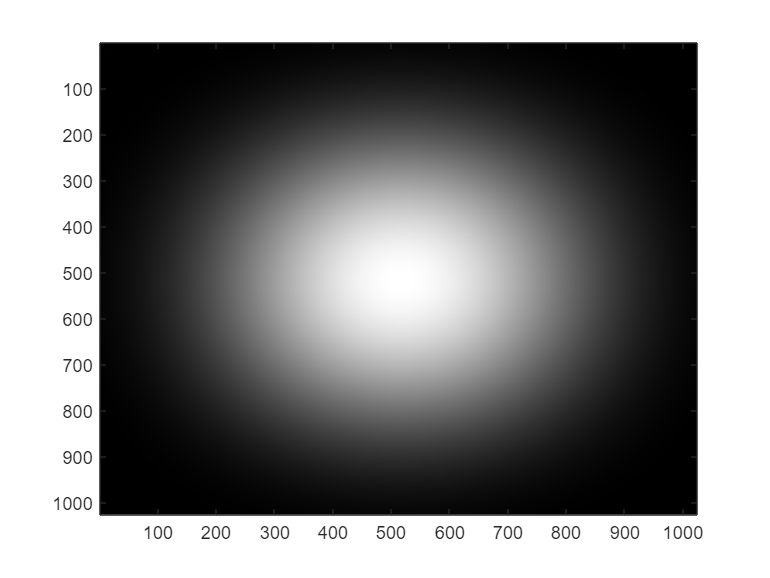

zPunto = 5*zlim;
fuentePuntual = transformadaFresnel(punto,dx,dy,zPunto,lambda,"dft",false,"zoom",true);
iluminacion= imresize(abs(fuentePuntual).^2,[Ny Nx]);
imagesc(iluminacion)

La iluminación que se usará será este frente de onda esférico

Se utiliza un obstaculo circular

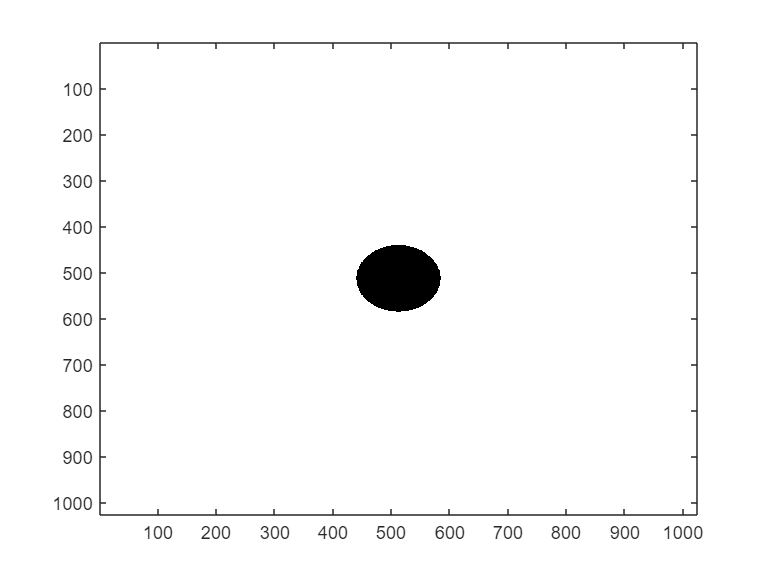

% Obstaculo 
obstaculoCircular = ~filtroCircular ([Nx/2 Ny/2],radioZonaFresnel/dx,[Ny Nx]);
imagesc(obstaculoCircular)
colormap gray

Se propaga el obstaculo iluminado con el frente de onda esférico

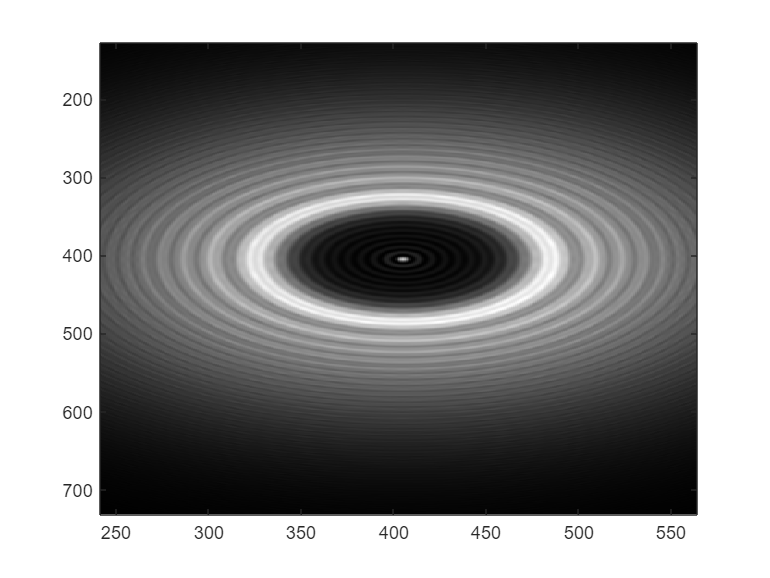

transmitancia = iluminacion.*obstaculoCircular;

propagacionArago = transformadaFresnel(transmitancia,dx,dy,z,lambda,"dft",false,"zoom",true);
intensidad = abs(propagacionArago).^2;
imagesc(intensidad)